# Ajuste del controlador PI utilizando NARMA-L2

Para que el modelo del controlador NARMA-L2 se ejecute, a continuación se indican cuales son sus constantes del motor DC

J=0.00048115; %Kg.m^2/s^2
B=0.0026829; %N.m
Km=0.22076; %N.m/A
Ka=0.22076; %V.s/rad
R=4.08; %Resistencia
L=0.011307; %Inductancia

Función de transferencia de la planta

G1=tf([Km],[L*J L*B+R*J R*B+Ka*Km]); %FT de la planta
Q=60/(2*pi); %Factor que transforma de rad/s a RPM
G=G1*Q %FT Velocidad/Voltaje

G =
 
                 2.108
  -----------------------------------
  5.44e-06 s^2 + 0.001993 s + 0.05968
 
Continuous-time transfer function.



Se inicializa el simulink con el modelo del controlador NARMA-L2

open_system("narma_controller.mdl")

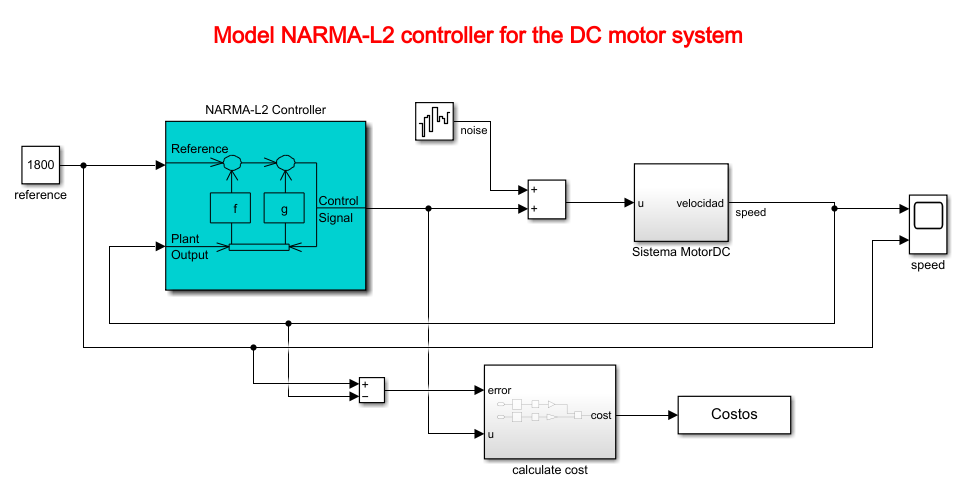

# Identificación de la planta

Se realiza la configuración del controlador NARMA-L2 donde se debe identificar el simulink de la planta, el cual se encuentra en el siguiente modelo

%open_system('model_motor.mdl')

Se realiza sus configuraciones del entrenamiento y se obtienen los siguientes datos

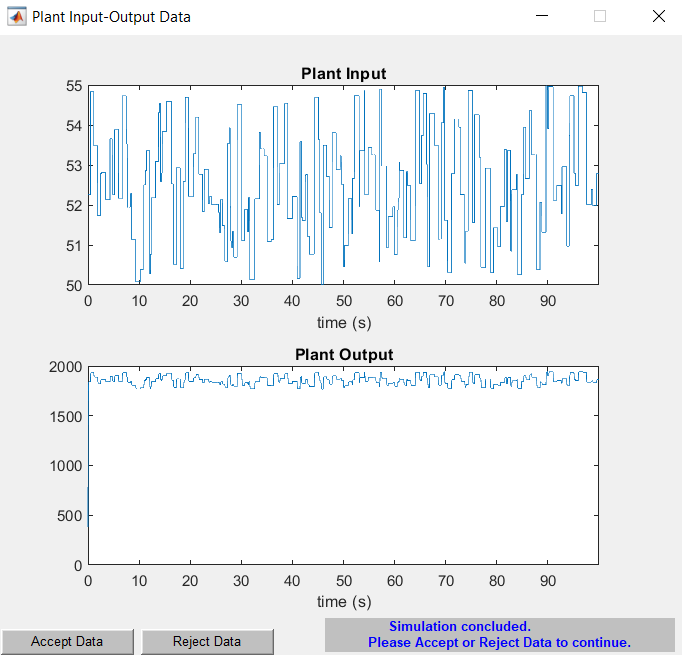

En la identificación de la planta, se encuentra con la entrada y su salida. En base como la señal de control ingresa al modelo, este tendrá una salida que es donde se encuentra nuestro punto de operación, que está en 1800 rpm. Para su identificación se realizaron 10000 muestras de entrenamiento con un intervalo de 0.1 y 1 segundos. El entrenamiento de los datos se los almacena en

load('training_data.mat')

Grafica del entrenamiento

Ts2=0.01;
Tiempo= 0:Ts2:100;
Tiempos= transpose(Tiempo);

figure(1)
subplot(2,1,1)
plot(Tiempos, tr_dat.U)
xlabel('samples [s]')
ylabel('Input')
title('Plant Input')
subplot(2,1,2)
plot(Tiempos, tr_dat.Y)
xlabel('samples [s]')
ylabel('Output')
title('Plant Output')

Luego se aceptan los datos y se procede a entrenar a la red neuronal, con los 1000 episodios similar a lo aplicado en el aprendizaje por refuerzo

Se grafica su respuesta del sistema considerando la red entrenada, se guardan sus datos en la siguiente variable

%save('Datos_model_con_ruido')
%save('Datos_model_sin_ruido')

En caso de realizar las respectivas pruebas, es importante la carga de sus datos

load('Datos_model_con_ruido')
load('Datos_model_sin_ruido')
load('simout_con_ruido')
load('simout_con_ruido')

A continuación se realizan las gráficas de la respuesta de los modelos con ruido y sin ruido

Gráfica con ruido

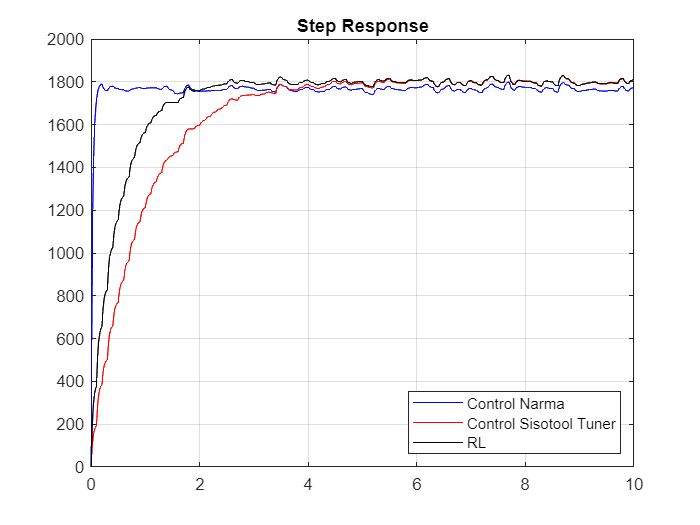

X_nar_ruid= Datos_model_con_ruido.time;
Y_nar_ruid= Datos_model_con_ruido.signals(1).values;

figure(25)
plot(X_nar_ruid,Y_nar_ruid,'blue')
hold on
plot(cstStep,'red')
hold on
plot(rlStep,'black')
grid on
legend('Control Narma ','Control Sisotool Tuner','RL','Location','southeast')
title('Step Response')

Gráfica sin ruido

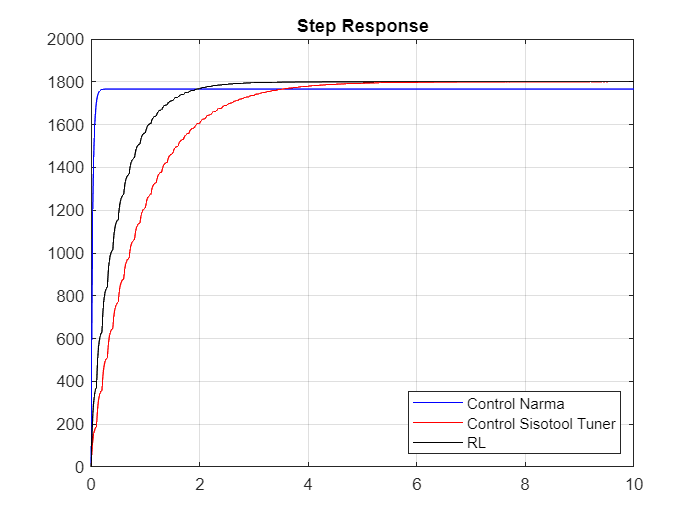

X_nar= Datos_model_sin_ruido.time;
Y_nar= Datos_model_sin_ruido.signals(1).values;

figure(36)
plot(X_nar_ruid,Y_nar_ruid,'blue')
hold on
plot(cstStep,'red')
hold on
plot(rlStep,'black')
grid on
legend('Control Narma ','Control Sisotool Tuner','RL','Location','southeast')
title('Step Response')

Se reaiza las metricas de evaulacion del controlador NARMA-L2

info_ruido= stepinfo(Y_nar_ruid,X_nar_ruid);
info_sin_ruido= stepinfo(Y_nar,X_nar);
stepInfoTable2 = struct2table([info_ruido info_sin_ruido]);
stepInfoTable2 = removevars(stepInfoTable2,{...
    'SettlingMin','SettlingMax','Undershoot','PeakTime'});
stepInfoTable2.Properties.RowNames = {'NARMA Ruido','NARMA sin Ruido'};
stepInfoTable2

stepInfoTable2 = 2×5 table
                       RiseTime    TransientTime    SettlingTime    Overshoot      Peak 
                       ________    _____________    ____________    __________    ______

    NARMA Ruido        0.062789       0.11346         0.11346           1.4933    1799.2
    NARMA sin Ruido    0.062414       0.11686         0.11686       0.00042129    1766.1


Se evaluan sus costos.

Costo_NARMA  = sum(Costos.Data)

Costo_NARMA = -8.2991e+06